Kp = 2;
Ti = 0.5;
Td = 0.2;
N = 10;


PID = pid(Kp, Kp/Ti, Td*Kp, Td/N)


PID =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 2, Ki = 4, Kd = 0.4, Tf = 0.02
 
Continuous-time PIDF controller in parallel form.
Model Properties


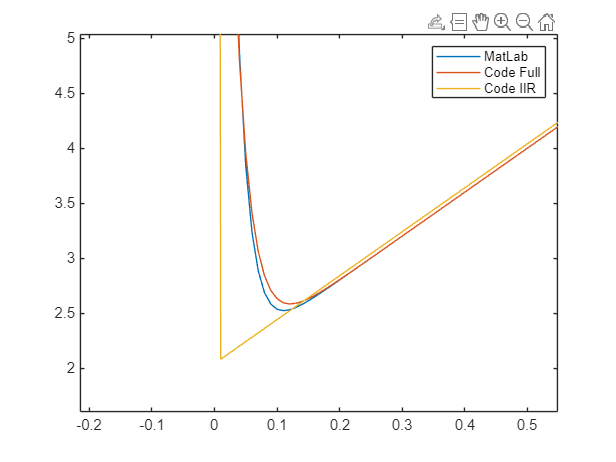


[y, t] = step(PID, 0:0.01:9.99);

y_code = readtable("PID_test.txt");

plot(t, [y, y_code.Var1 y_code.Var2])
legend("MatLab", "Code Full", "Code IIR")